## 参数设置

clear;clc;
%参数
% syms x t F f M m I g l b;
M = 0.5;
m = 0.2;
l = 0.3;
I = 0.018;
g = 9.8;
b = 0.1;

## 状态矩阵


$$\dot{x}=Ax+Bu\\
y=Cx+Du$$



$$x=
\left[
\matrix{
x  & \dot{x}  & \theta  & \dot{\theta }}
\right]
$$


a=(M+m)*I+M*m*l^2;
A=[0 1 0 0;
    0, -b*(I+m*l^2)/a, m^2*l^2*g/a 0;
    0 0 0 1;
    0, -b*m*l/a, (M+m)*m*g*l/a 0];
B=[0 ;
   (I+m*l^2)/a;
   0;
   m*l/a];
C=[1 0 0 0;
    0 0 1 0];
D=[0 ;
    0];

## MPC


$$x(k+1)=Ax(k)+Bu(k)$$


n = size(A,1);
p = size(B,2);
T = 0.1;
A_ = eye(n) + A*T;
B_ = B*T;

x0 = [0;0;0;0];
ref = [1;0;0;0];
N = 10;
X_ref = repmat(ref,N+1,1);

%权重矩阵
Q = [1 0 0 0;
     0 1 0 0;
     0 0 1 0;
     0 0 0 1];
F = [1 0 0 0;
     0 1 0 0;
     0 0 1 0;
     0 0 0 1];
R = 0.1;
lb = -100;
ub = 100;

refs = repmat(ref,N,1);

for i = 1:200
    u2 = MPC_Controller(A_,B_,N,n,p,Q,F,R,lb,ub,x0,X_ref);
    %u1 = SolveLinearMPC(A_, B_, x0*0, Q, R, lb, ub, x0, refs, N);
    u = u2(1);
    x0 = A_*x0+B_*u;
    X_K(:,i) = x0;
    U_K(:,i) = u;

end


找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>



找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>




%画图
    subplot(2, 1, 1);
    hold;

已锁定最新绘图



    for i =1 :size (X_K,1)
        plot (X_K(i,:));
    end

    legend("x1","x2","x3","x4")
    hold off;
    subplot (2, 1, 2);
    hold;

已锁定最新绘图


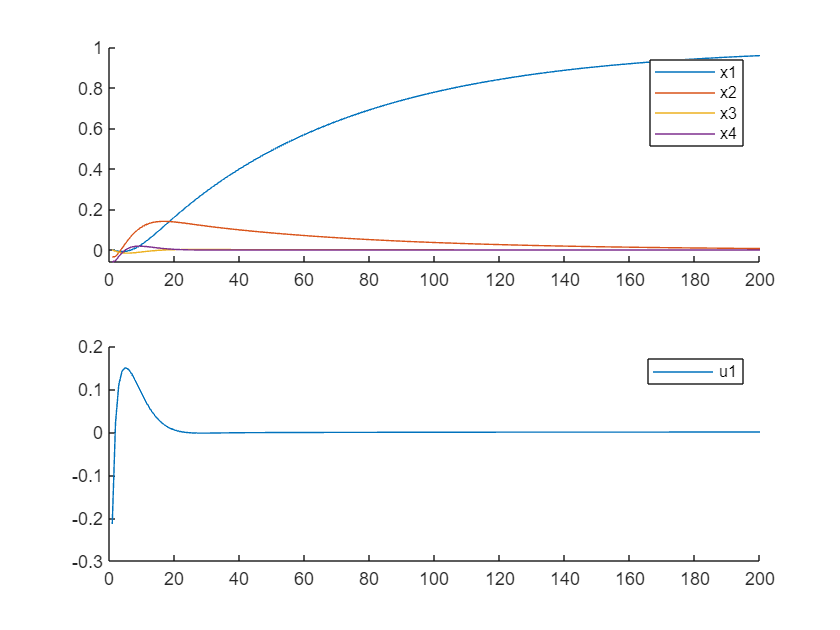

    
    for i =1 : size (U_K,1)
        plot (U_K(i,:));
    end
    legend("u1")

function u = MPC_Controller(A_,B_,N,n,p,Q,F,R,lb,ub,x0,X_ref)
    tmp = eye(n);
    M = eye(n*(N+1),n);
    C = zeros(n*(N+1),p*N);
    for i = 1:N
        rows = i*n+(1:n);
        C(rows,:) = [tmp*B_,C(rows-n,1:end-p)];
        tmp = tmp*A_;
        M(rows,:) = tmp;
    end
    Q_ = kron(eye(N),Q);
    Q_ = blkdiag(Q_,F);
    R_ = kron(eye(N),R);
    % M1=M*x0;
    H = 2*(C'*Q_*C+R_);
    f = 2*(M*x0-X_ref)'*Q_*C;

    lb = repmat(lb,N,1);
    ub = repmat(ub,N,1);

    u = quadprog(H,f',[],[],[],[],lb,ub);
    u = u(1:p,1);
end
